# **ESERCIZIO 6C**

**Given the continous time LTI system described by the G(s) = **$\frac{-7044}{s^2 -881}$, **assume a sampling time of 1ms. Design a digital controller using as 1dof architecture to meet the following requirements:**

- $|e_r^{\infty } |=0$**in the presence of a step reference signal**

- 
$$\hat{s} \le 25%$$


- 
$$t_r \le 0\ldotp 015s$$


format compact
s = tf('s');
ts = 0.001;
z = tf('z',ts);
G_cont = -7044/(s^2-881);

la funzione `c2d` mi trasforma una funzione da continua in discreta

G_disc = zpk(c2d(G_cont,ts,'zoh'))

G_disc =
 
   -0.0035223 (z+1)
  -------------------
  (z-1.03) (z-0.9708)
 
Sample time: 0.001 seconds
Discrete-time zero/pole/gain model.



[z_G, p_G, k_G] = zpkdata(G_disc,'v')

z_G = -1.0000

p_G =     1.0301
    0.9708


k_G = -0.0035

Definisco i polinomi $B\left(z\right),A\left(z\right)$ $\to$ $G\left(z\right)=\frac{B\left(z\right)}{A\left(z\right)}$

B = k_G*[1 -z_G];
A = conv([1 -p_G(1)], [1 -p_G(2)]);

Per garantire $|e_r^{\infty } |=0$ è necessario un polo in 1 in $L\left(z\right)=C\left(z\right)\cdot G\left(z\right)$

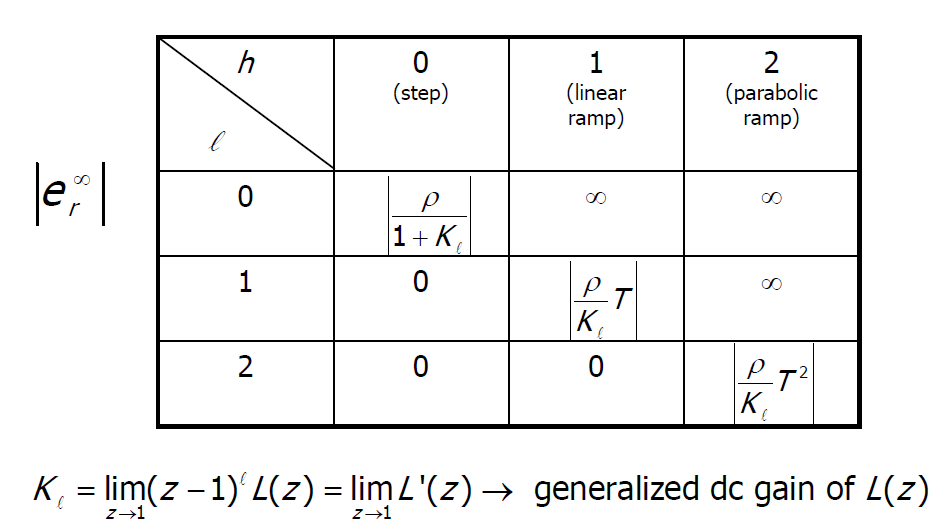

qui $G\left(z\right)$ non ha un polo in 1 quindi non devo aggiungerne in $C\left(z\right)=\frac{S\left(z\right)}{\left(z-1\right)R^{\prime } \left(z\right)}$ 

Impongo i requisiti per zeta per soddisfare $\hat{s} \le 25%$ $\to \zeta \ge \frac{|\log \left(\hat{s} \right)|}{\sqrt{\pi^2 +\log^2 \left(\hat{s} \right)}}$

s_hat = 0.25;
zeta = abs(log(s_hat))/(sqrt(pi^2 + (log(s_hat))^2))

zeta = 0.4037

            se imposto la $\zeta$ molto più bassa (=0.95) posso togliere l'overshoot nella figura finale

%zeta = 0.95
t_r = 0.015;
wn = 1/(t_r*sqrt(1 - zeta^2))*(pi -acos(zeta))

wn = 144.7443

Scelgo di cancellare gli zeri e i poli nell'area descritta dai requisiti di zeta ($\zeta \ge 0\ldotp 4037$).

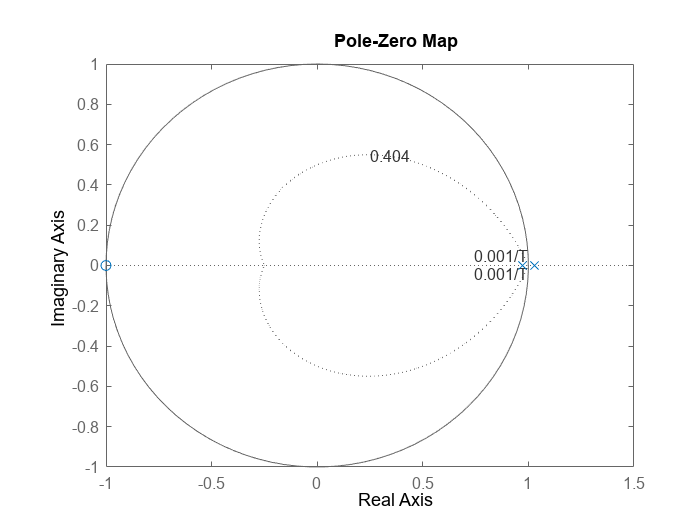

figure
pzmap(G_disc)
hold on 
zgrid(zeta,ts)

A_plus = [1 -p_G(2)];
A_minus = [1 -p_G(1)];
B_plus = 1;
B_minus = B;

Le condizioni sui gradi sono: 


$$\begin{array}{l}
\deg \left(S^{\prime } \left(z\right)\right)=l+\deg \left(A^- \left(z\right)\right)-1=l_1 +l_2 +\deg \left(A^- \left(z\right)\right)-1=0\;+1+1-1=1\\
\deg \left(R^{\prime } \left(z\right)\right)=\deg \left(A^{\prime } \left(z\right)\right)-\deg \left(B^+ \left(z\right)\right)+l_1 -1=\;2-0+0-1=1\\
\deg \left(A_m \left(z\right)\right)=l+\deg \left(A^{\prime } \left(z\right)\right)+\deg \left(A^- \left(z\right)\right)+l_1 -\deg \left(B^+ \left(z\right)\right)-1=1+2+1+0-0-1=3\;\left(3\;\textrm{poli}\;\textrm{da}\;\textrm{piazzare}\;\textrm{in}\;C\left(z\right)\right)
\end{array}$$
 


$$C\left(z\right)=\frac{A^+ \left(z\right)\cdot \left(s_1 \cdot z+s_0 \right)}{\left(z-1\right)\cdot B^+ \left(z\right)\cdot \left(r_1 \cdot z+r_0 \right)}$$


Devo scegliere 3 poli $p_a ,p_b ,p_c$: il terzo polo deve avere una costante di tempo più veloce rispetto alla coppia di poli complessi coniugati (per non influezarne il comportamento):

p1c = -zeta*wn +j*wn*sqrt(1-zeta^2);
p2c = -zeta*wn -j*wn*sqrt(1-zeta^2);
p3c = -5*zeta*wn;
p1 = exp(ts*p1c)

p1 = 0.9350 + 0.1245i

p2 = exp(ts*p2c)

p2 = 0.9350 - 0.1245i

p3 = exp(ts*p3c)

p3 = 0.7466

Am = poly ([p1 p2 p3])

Am =     1.0000   -2.6166    2.2859   -0.6643


A_dioph = conv([1, -1], A_minus)

A_dioph =     1.0000   -2.0301    1.0301


B_dioph = B_minus

B_dioph =    -0.0035   -0.0035


Gamma = Am';
M_s = [[A_dioph(:);0],[0;A_dioph(:)],[0;B_dioph(:);0],[0;0; B_dioph(:)]]

M_s =     1.0000         0         0         0
   -2.0301    1.0000   -0.0035         0
    1.0301   -2.0301   -0.0035   -0.0035
         0    1.0301         0   -0.0035


theta = M_s\Gamma;
R1 = theta(1:2)'

R1 =     1.0000   -0.6173


S1 = theta(3:4)'

S1 =    -8.7605    8.0506


R = conv([1 -1],R1)

R =     1.0000   -1.6173    0.6173


S = conv(A_plus, S1)

S =    -8.7605   16.5548   -7.8151


C = zpk(tf(S,R,ts))

C =
 
  -8.7605 (z-0.9708) (z-0.919)
  ----------------------------
        (z-1) (z-0.6173)
 
Sample time: 0.001 seconds
Discrete-time zero/pole/gain model.



W = minreal(zpk(feedback(C*G_disc,1)),1e-2)

W =
 
      0.030857 (z+1) (z-0.919)
  ---------------------------------
  (z-0.7466) (z^2 - 1.87z + 0.8897)
 
Sample time: 0.001 seconds
Discrete-time zero/pole/gain model.



poles = pole(W)

poles =    0.7466 + 0.0000i
   0.9350 + 0.1245i
   0.9350 - 0.1245i


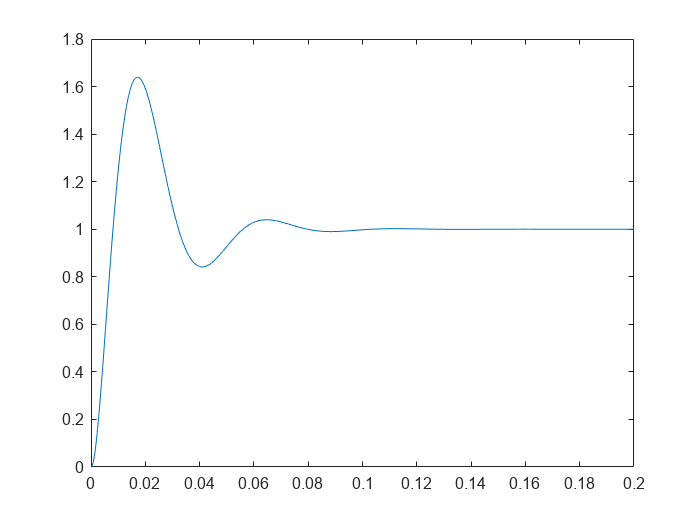

tsim = 0.2; 
out = sim('DC_6c');
figure
plot(out.y.time,out.y.data)

# **ESERCIZIO 7A - CONTINUAZIONE ES 6C**

**2 DEGREES OF FREEDOM ARCHITECTURE**

Implemento l'architettura con 2 gradi di libertà per poter controllare gli zeri e imporre una condizione sul guadagno $k_T$. Voglio cancellare lo zero che mi ha dato problemi di overshoot nel vecchio controllore. Implemento una $F\left(z\right)=\frac{T^{\prime } \left(z\right)}{S^{\prime } \left(z\right)}$, so che il grado di $S^{\prime } \left(z\right)=1$ quindi il grado di $T^{\prime } \left(z\right)=1$ 

($\left.F\left(z\right)\;\textrm{deve}\;\textrm{essere}\;\textrm{propria}\right)$. $T^{\prime } \left(z\right)=k_1 \tilde{T} \to \deg \left(\tilde{T} \right)=1$, $\deg \left(A^0 \left(z\right)\right)=1\to T^{\prime } \left(z\right)=k_T A^0 \left(z\right)$ (in modo da eliminare lo zero).

$k_T =k_w \cdot \frac{S^{\prime } \left(z\right)}{\tilde{T} \left(1\right)\cdot W^{\prime } \left(1\right)}$. Per soddisfare $|e_r^{\infty } |=0$ deve essere $l\ge 1$ e $k_w =1$ ($\left.l=1\;\textrm{per}\;\textrm{via}\;\textrm{di}\;C\left(z\right)\;\textrm{che}\;\textrm{abbiamo}\;\textrm{già}\;\textrm{imposto}\right)$.

T_tilde = [1 -p3]

T_tilde =     1.0000   -0.7466


kW = 1;
kT = kW*polyval(S1,1)/(polyval(T_tilde,1)*dcgain(W))

kT = -2.8020

W

W =
 
      0.030857 (z+1) (z-0.919)
  ---------------------------------
  (z-0.7466) (z^2 - 1.87z + 0.8897)
 
Sample time: 0.001 seconds
Discrete-time zero/pole/gain model.



T1 = kT*T_tilde

T1 =    -2.8020    2.0921


F = zpk(tf(T1,S1,ts))

F =
 
  0.31984 (z-0.7466)
  ------------------
      (z-0.919)
 
Sample time: 0.001 seconds
Discrete-time zero/pole/gain model.



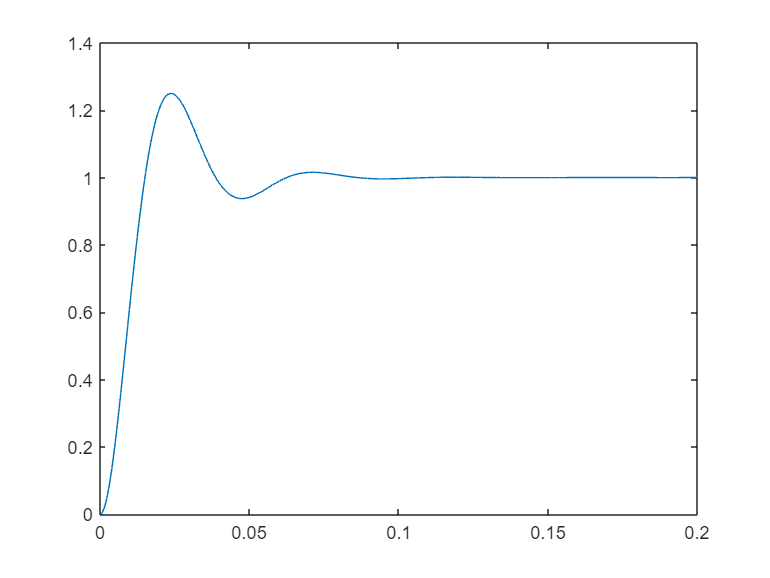

out = sim('DC_7a');
figure
plot(out.y.time,out.y.data)